structure_stl = "structure.stl";
print_stl = "print.stl";

% How much to translate the structure
ts = [0 0 0];
% How much to rotate the structure
rs = [-90 0 0];

% 1 means all inputs are in degrees
deg = 1;

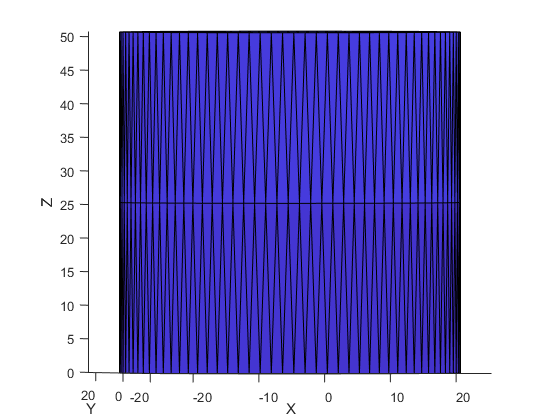

[P,T,N]=import_stl_fast(structure_stl,1);

[P, N] = rotate_mesh(P,N,rs,deg);
P = translate_mesh(P,ts);

patch('Faces', T, 'Vertices', P, 'FaceVertexCData', (1:length(T(:,1)))', 'FaceColor', 'flat');
view(3)
axis equal
zlabel('Z');xlabel('X');ylabel('Y');